clc,clear

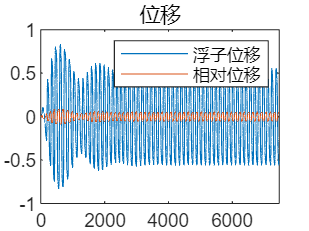

%initialize parameter
g=9.8;                                   %重力加速度 (m/s2)
%l0=0.5;                                 %弹簧原长 (m)       
dt=0.2;                                  %步长设为0.2s
w=1.7152;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）
T=2*pi/w;
T_end=floor(80*T);                       %总数值模拟时间(s) 
%%初值设置               
v1=0;                                    %浮子的初始速度 (m/s)
v2=0;                                    %振子的初始速度 (m/s)
x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
x_v=0;                                   %振子的初始位移 (m)
theta1=0;
theta2=0;
omega1=0;
omega2=0;
X0=[x_f;x_v;v1;v2;theta1;theta2;omega1;omega2];
tspan=[0,T_end];
options = odeset('MaxStep', 0.1);  % 设置最大步长为 0.2
[~, X] = ode45(@S_diff_equ, tspan, X0, options);
X=X';
plot(X(1,:))
title('位移')
hold on 
x=X(1,:)-X(2,:);
plot(x)
legend('浮子位移','相对位移')
hold off

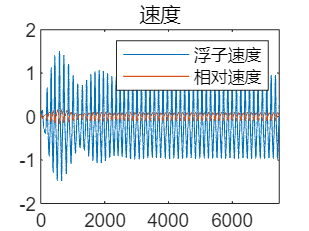

plot(X(3,:))
title('速度')
hold on
plot(X(3,:)-X(4,:))
legend('浮子速度','相对速度')
hold off

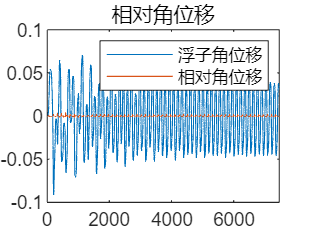

plot(X(5,:))
title('角位移')
hold on 
x=X(5,:)-X(6,:);
plot(x)
legend('浮子角位移','相对角位移')
hold off
title('相对角位移')

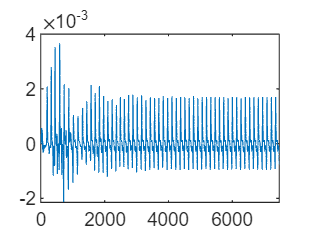

x=X(5,:)-X(6,:);
plot(x)
hold off

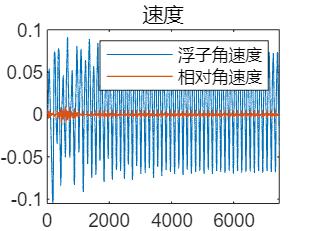

时间 (s)	浮子		  振子 
		位移 	速度 	  位移 	     速度 

   10.0000    0.0629    0.1437    0.0555    0.1879    0.0165    0.0487    0.0161    0.0519



   20.0000    0.0469   -0.2641    0.0665   -0.2722    0.0544    0.0021    0.0545    0.0036



   40.0000    0.0659    0.6604    0.0520    0.7271   -0.0866   -0.0339   -0.0885   -0.0356



   60.0000   -0.5542   -0.1816   -0.6059   -0.2410   -0.0063   -0.0227   -0.0062   -0.0223



  100.0000    0.6266   -0.9040    0.7046   -0.9640   -0.0450    0.0370   -0.0451    0.0380



plot(X(7,:))
title('速度')
hold on
%初步计算  不考虑耦合
plot(X(7,:)-X(8,:))  %数量级为1e-3 稳定后二者相对位移是小量
legend('浮子角速度','相对角速度')
hold off

function dxdt=S_diff_equ(t,X)
    k1=1e+4;
    k2=1000;
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    h_v=0.5;                                 %振子高度
    r_v=0.5;                                 %振子底半径
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1028.876;                          %垂荡附加质量 (kg)
    J_add=7001.914;                          %纵摇附加转动惯量 (kg·m2)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke1=80000;                               %直线弹簧刚度 (N/m)
    ke2=250000;                              %旋转弹簧刚度
    w=1.7152;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr1=683.4558;                            %垂荡兴波阻尼系数 (N·s/m)
    kr2=654.3383;                            %纵摇兴波阻尼系数 (N·m·s)
    f_max=3640;                              %垂荡激励力振幅 (N)
    M_max=1690;                              %纵摇激励力矩振幅 (N·m)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;        %水面的高度(m)
    l0=0.5-m2*g/ke1;                         %弹簧初始长度
    k_f=8890.7;                              %静水恢复力矩系数
    J1=8.4223e+03;
    J2=m2*(h_v^2/12+r_v^2/4)+m2*(h_v/2+l0+X(4))^2;
    dxdt=zeros(8,1);
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k1*(X(3)-X(4))-ke1*(X(1)-X(2))+f_max*cos(w*t)-kr1*X(3)-rho*g*pi*r_cost^2*X(1))/(m1+m_add);
    dxdt(4)=(k1*(X(3)-X(4))+ke1*(X(1)-X(2)))/m2;
    dxdt(5)=X(7);
    dxdt(6)=X(8);
    dxdt(7)=(-k2*(X(7)-X(8))-ke2*(X(5)-X(6))+M_max*cos(w*t)-kr2*X(7)-k_f*X(5))/(J1+J_add);
    dxdt(8)=(k2*(X(7)-X(8))+ke2*(X(5)-X(6)))/J2;
end